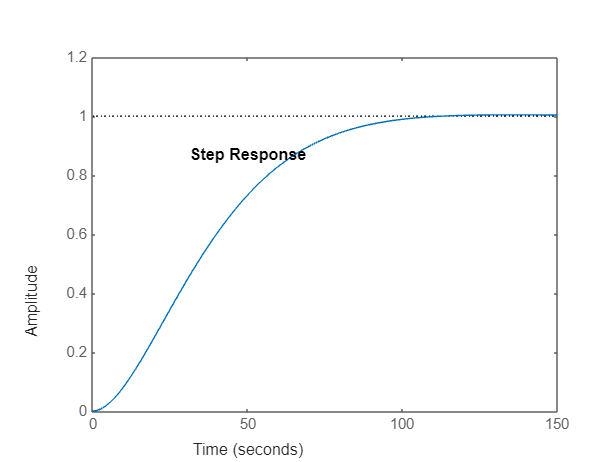

ans = struct with fields:
         RiseTime: 59.0330
    TransientTime: 93.7537
     SettlingTime: 93.7537
      SettlingMin: 0.9061
      SettlingMax: 1.0044
        Overshoot: 0.4445
       Undershoot: 0
             Peak: 1.0044
         PeakTime: 135.8525


% Definir el tiempo de asentamiento deseado
    Ts = 100; % segundos

    % Calcular los parámetros de la función de transferencia
    zeta = 0.865; % coeficiente de amortiguamiento (ajustar según sea necesario)
    wn = 4 / (zeta * Ts); % frecuencia natural

    % Crear la función de transferencia
    sys = tf(wn^2, [1, 2*zeta*wn, wn^2]);
    step(sys); stepinfo(sys)

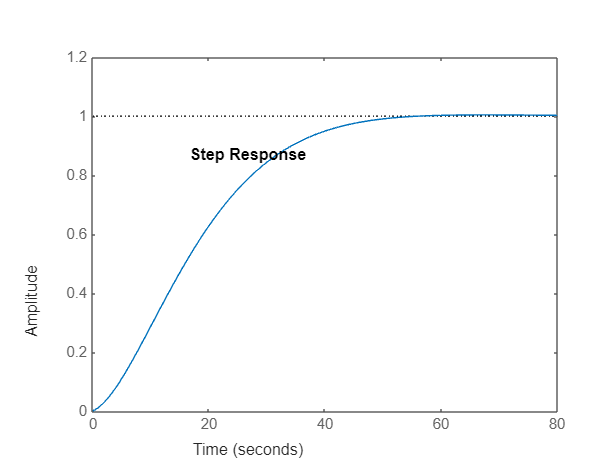

ans = struct with fields:
         RiseTime: 29.6225
    TransientTime: 46.2232
     SettlingTime: 46.2232
      SettlingMin: 0.9025
      SettlingMax: 1.0042
        Overshoot: 0.4194
       Undershoot: 0
             Peak: 1.0042
         PeakTime: 67.3506


% ref.km  = 0.21261;
% ref.bm  = 1;
% ref.am1 = 0.8;
% ref.am2 = 0.2126;
% ref.km  = 0.21261;
% ref.bm  = 1;
% ref.am1 = 0.8;
% ref.am2 = 0.2126;
ref.km  = 0.008504347681652;
ref.bm  = 1;
ref.am1 = 0.160000000000000;
ref.am2 = 0.008504347681652;
sys2=tf([ref.km ref.km*ref.bm],[1 ref.am1 ref.am2]);
step(sys2); stepinfo(sys2)


openLoop = feedback(sys2,1,+1);
openLoop

openLoop =
 
  0.008504 s + 0.008504
  ---------------------
     s^2 + 0.1515 s
 
Continuous-time transfer function.
Model Properties
